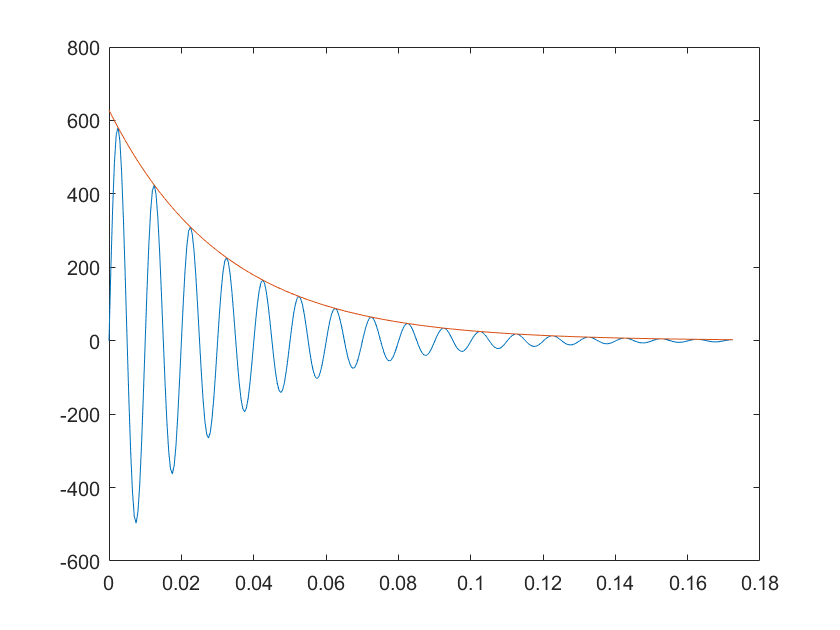

s = tf('s');

w = 100*2*pi; % natural frequency 100 Hz
zeta = 0.05;  % damping ratio 0.05
sys = w^2 / (s^2 + 2*zeta*w*s + w^2); % system
[y,t]=impulse(sys); % impulse response
plot(t,y,t,w*exp(-zeta*w*t)) % See the exponential envelope
                             % In here I knew exactly what zeta was
                             % You need to play with the number until 
                             %   the term envelops as shown in figure
                             % Also due to how I created the impulse response,
                             %   the gain of the exponential term was equal to 
                             %   w, you need to pick your gain depending on
                             %   the initial value of your response 
                             %   for you 0.6185 might work if you shift your
                             %   signal to start at 0 seconds
w_estimate = 1/(0.0175-0.0075); % From graph, find time value
                                %   for 2 consecutive peaks
                                % inverse the time difference
                                %   to obtain natural frequency
                                %   in Hz